# 需求分析：Otsu、最大熵法计算阈值

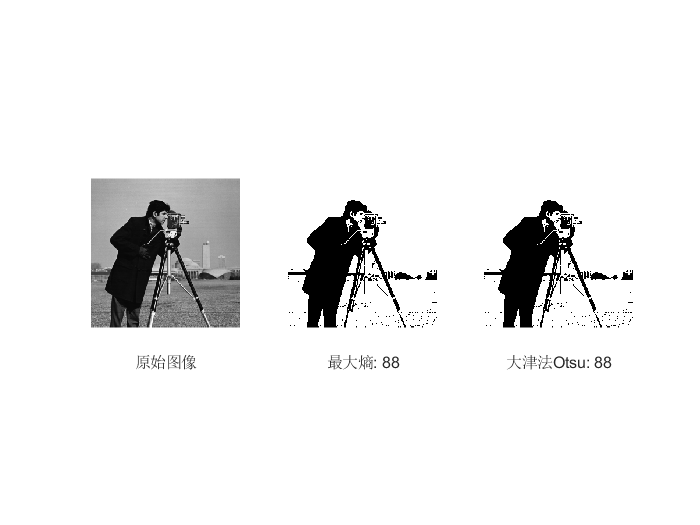

clear; clc;
I = imread('cameraman.tif');
subplot(1, 3, 1)
imshow(I);
xlabel('原始图像');
II = double(I);
% 使用最大熵计算阈值
level1 = ThresholdMaxEntropy(II);      
BW = imbinarize(I, level1 / 255);     
subplot(1, 3, 2)
imshow(BW);
xlabel(['最大熵: ', num2str(level1)]);
% 使用大津法计算阈值
level2 = ThresholdOtsu(II);                
BW = imbinarize(I, level2 / 255);
subplot(1, 3, 3)
imshow(BW);
xlabel(['大津法Otsu: ', num2str(level2)]);

function threshValue = ThresholdMaxEntropy(imgData)
% 最大熵计算阈值
% 输入：
%    imgData：二维数组，数值表示灰度；
% 输出：
%    threshValue：阈值
[X, Y] = size(imgData);
vMax = max(imgData(:));
vMin = min(imgData(:));
% 初始分割阈值
T0 = (vMax + vMin) / 2;       
% 计算图像的直方图
h = GetImageHist(imgData);   
% 图像像素概率
grayP = h / (X * Y);               
% 计算初始熵
H0 = 0;
for i = 1 : 256
    if grayP(i) > 0
        H0 = H0 - grayP(i) * log(grayP(i));
    end
end
% 开始迭代计算
% 设置最大迭代次数
cout = 100;      
while cout > 0
    % 初始化
    Tmax = 0;            
    T1 = T0;   
    % 分割区域 G1 的点数
    A1 = 0;   
    % 分割区域 G2 的点数
    A2 = 0;     
    % 分割区域 G1 的灰度总和
    B1 = 0;    
    % 分割区域 G2 灰度总和
    B2 = 0;      
    % 计算灰度平均值
    for i = 1 : X        
        for j = 1 : Y
            if(imgData(i, j) <= T1)
                A1 = A1 + 1;
                B1 = B1 + imgData(i, j);
            else
                A2 = A2 + 1;
                B2 = B2 + imgData(i, j);
            end
        end
    end
    % 分割区域G1的平均灰度
    M1 = B1 / A1;     
    % 分割区域G2的平均灰度
    M2 = B2 / A2;   
    % 更新阈值
    T2 = (M1 + M2) / 2;        
    TT = floor(T2);
    % 计算分割区域G1的概率和
    grayPd = sum(grayP(1 : TT));    
    if grayPd == 0
        grayPd = eps;
    end
    grayPb = 1 - grayPd;
    if grayPb == 0
        grayPb = eps;
    end
    % 计算分割后区域 G 1和 G2 的信息熵
    Hd = 0;
    Hb = 0;
    for i = 1 : 256
        if i <= TT
            if grayP(i) > 0
                Hd = Hd - grayP(i) / grayPd * log(grayP(i) / grayPd);
            end
        else
            if grayP(i) > 0
                Hb = Hb - grayP(i) / grayPb * log(grayP(i) / grayPb);
            end
        end
    end
    % 总的熵
    H1 = Hd + Hb;      
    % 退出条件
    if abs(H0 - H1) < 0.0001 
        Tmax = T2;
        break;
    else 
        T0 = T2;
        H0 = H1;
    end
    cout = cout - 1;
end
% 返回阈值
threshValue = floor(Tmax);
end

% 灰度直方图
function h = GetImageHist(Imag)
h = zeros(256, 1);
for k = 1 : 256
    h(k) = 0;
    for i = 1 : size(Imag, 2)
        for j = 1 : size(Imag, 2)
            if Imag(i, j) == k - 1
                h(k) = h(k) + 1;
            end
        end
    end
end
end

function threshValue = ThresholdOtsu(imgData)
% 大津法计算阈值
% 输入：
%    imgData：二维数组，数值表示灰度；
% 输出：
%    threshValue：阈值
iMax = max(imgData(:));               % 最大值
iMin = min(imgData(:));               % 最小值
T = iMin : iMax;                      % 灰度值范围
Tval = zeros(size(T));                % 方差
[iRow, iCol] = size(imgData);         % 数据维度大小
imagSize = iRow * iCol;              % 像素点数量
% 遍历灰度值，计算方差
for i = 1 : length(T)
    TK = T(i);
    iFg = 0;          % 前景
    iBg = 0;          % 背景
    FgSum = 0;        % 前景总数
    BgSum = 0;        % 背景总数
    for j = 1 : iRow
        for k = 1 : iCol
            temp = imgData(j, k);
            if temp > TK
                iFg = iFg + 1;      % 前景像素点统计
                FgSum = FgSum + temp;
            else
                iBg = iBg + 1;      % 背景像素点统计
                BgSum = BgSum + temp;
            end
        end
    end
    w0 = iFg / imagSize;      % 前景比例
    w1 = iBg / imagSize;      % 背景比例
    u0 = FgSum / iFg;         % 前景灰度平均值
    u1 = BgSum / iBg;         % 背景灰度平均值
    Tval(i) = w0 * w1 * (u0 - u1) * (u0 - u1);     % 计算方差
end
[~, flag] = max(Tval);             % 最大值下标
threshValue = T(flag);
end